# Actividad 4.1 (Evaluación)

**Implementar** el código requerido para generar las siguientes trayectorias a partir de las velocidades angulares y lineales en un plano 2D.

**Trayectoria 1:**

**X= [0 a 5]**

**F(x) = 2*sen(****x^2****)**

1. Definimos la función de la trayectoria a parametrizar.

2. Realizamos la paramterízación de las funciones respecto al tiempo:

    **x(t)=t**

    **y(t)=2*sen(t^2)**

      3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

    **x ̇(t)=1**

**    y ̇(t)=4t*cos(t^2)**

      4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(4t*cos(t^2))^2 )**

5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (4t*cos(t^2))**

6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(-8t^2*sen(t^2)+4*cos(t^2)/(****1+(4t*cos(t^2))****^****2 )**

7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.1;            
t = 0: ts: 5;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

% Condiciones de la trayectoria específicas
x1(1) = 0;              
y1(1) = 0;              
phi(1) = 0;       

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); % velocidad lineal
w = zeros(1,N); % velocidad angular

for k = 1:N
    
    tk = t(k);
    
    dx = 1;
    dy = 4*tk*cos(tk^2);
    
    % Velocidad lineal
    u(k) = sqrt(dx^2 + dy^2);
    
    % Velocidad angular
    w(k) = ((-8*(tk^2)*sin(tk^2))+(4*cos(tk^2))) / (1 + (dy)^2);
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([5 40]); % Orientacion de la figura
axis([-1 6 -3 3 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 0.5;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

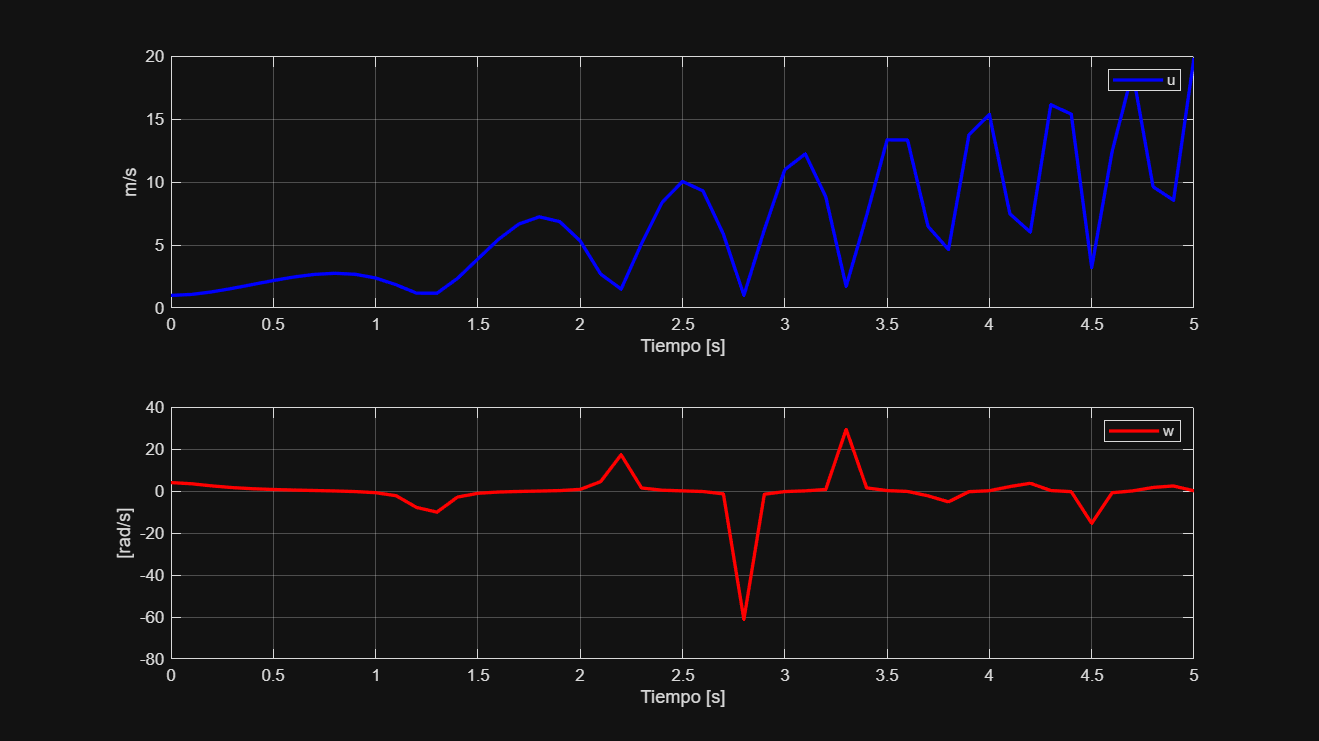


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

**Trayectoria 2:**

**X= [0 a 5]**

**F(x) = x^2 + y^2 -16**

Pasamos de coordenadas cartesianas a coordenadas polares y seguimos con el procedimiento:

2. Realizamos la paramterízación de las funciones respecto al tiempo:

    **x(t)=4*cos(t)**

    **y(t)=4*sen(t)**

      3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

    **x ̇(t)=-4*sen(t)**

**    y ̇(t)=4*cos(t)**

      4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√((-4*sen(t))^2+(4*cos(t))^2 )**

5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (-cot(t))**

6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(csc^2(t))/(****1+(-cot(t))****^****2 )**

7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

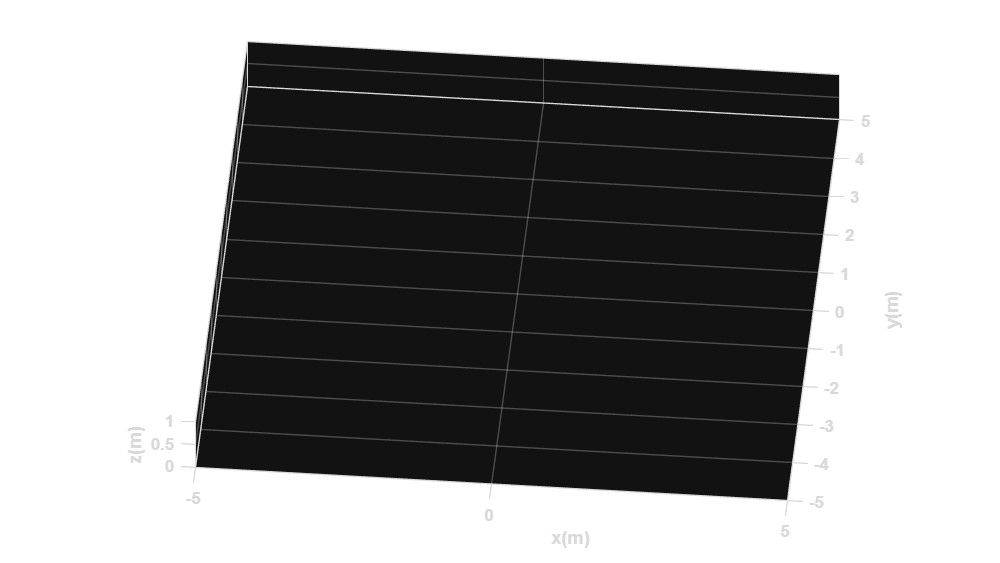

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.1;            
t = 0: ts: 2*pi;       
N = length(t);     

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

% Condiciones de la trayectoria específicas
x1(1) = 0;              
y1(1) = 4;              
phi(1) = atan(0);       

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); % velocidad lineal
w = zeros(1,N); % velocidad angular

for k = 1:N
    
    tk = t(k);
    
    dx =  -4*sin(tk);
    dy =   4*cos(tk);
    ddx = -4*cos(tk);
    ddy = -4*sin(tk);
    
    % Velocidad lineal
    u(k) = sqrt(dx^2 + dy^2);
    
    % Velocidad angular
    w(k) = ((csc(tk))^2) / (1 + (-cot(tk))^2);
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([5 40]); % Orientacion de la figura
axis([-5 5 -5 5 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 0.5;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

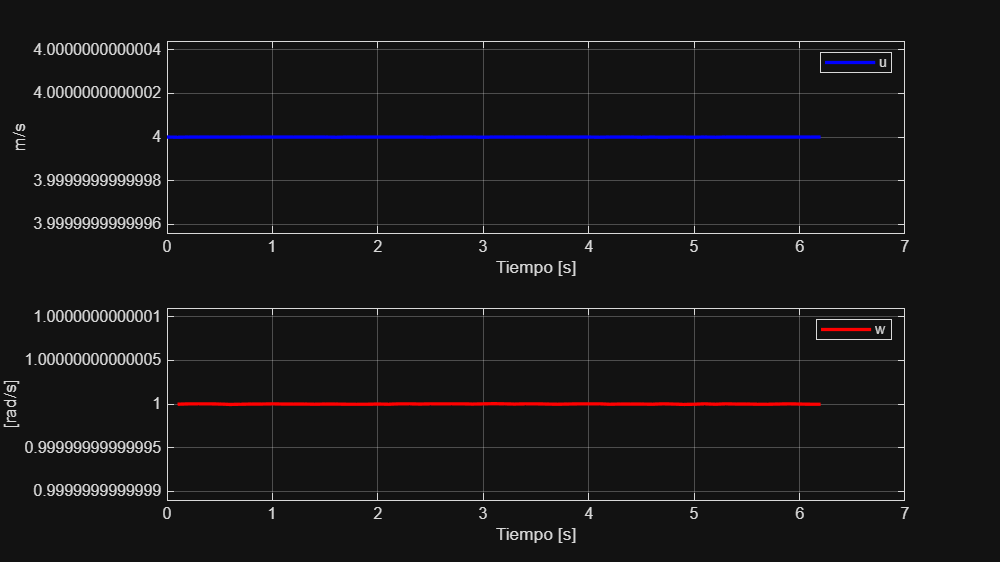


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

**Trayectoria 3**

Para cada parte de la función a trozos, es necesario realizar el proceso de paramaterízación en seguimiento de trayectorias:

- **Tramo 1**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=2t**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)=2**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(2)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (2)**

                6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(0)/(****1+(2)****^****2 )**

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

- **Tramo 2**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=2t+1**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)=2**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(2)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (2)**

                6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(0)/(****1+(2)****^****2 )**

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

- **Tramo 3**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=-t+4**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)=-1**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(-1)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (-1)**

                6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(0)/(****1+(-1)****^****2 )**

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

- **Tramo 4**

                1. Definimos la función de la trayectoria a parametrizar.

                2. Realizamos la paramterízación de las funciones respecto al tiempo:

                    **x(t)=t**

                    **y(t)=t-1**

                3. Calculamos las derivadas de las funciones para obtener las velocidades en cada eje:

                    **x ̇(t)=1**

**                    y ̇(t)=1**

                4. Obtenemos la expresión matemática para la velocidad lineal **u(t): u(t)=√(1+(1)^2 )**

                5. Calculamos la expresión del ángulo de orientación **θ(t): θ****(t)= arctan (1)**

                6. Obtenemos la expresión matemática para la velocidad angular **ω(t): ω****(t)=****(0)/(****1+(1)****^****2 )**

                7. Finalmente obtenemos la expresión matemática para la velocidad lineal **u(t)** y la velocidad angular **ω(t)**.

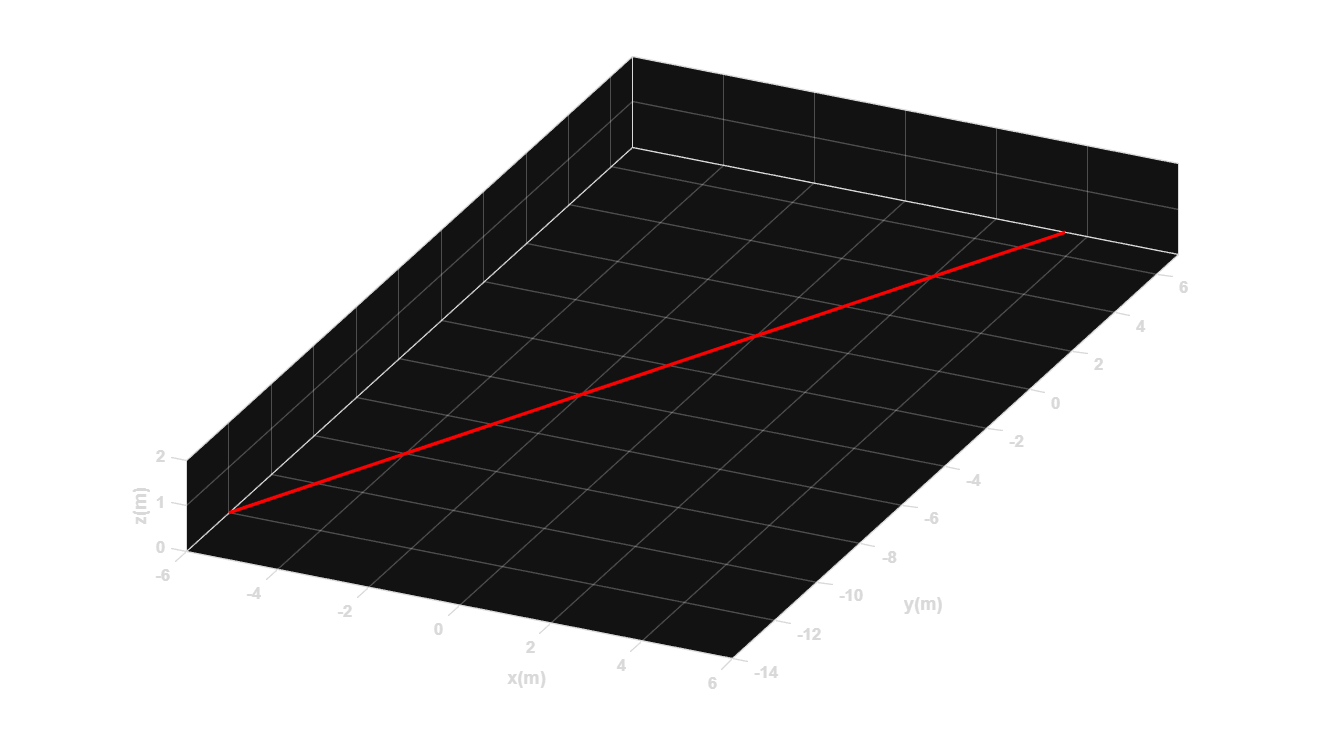

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
             
ts = 0.1;            
t = -6: ts: 6;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

x1(1) = -6;              
y1(1) = -12;              
phi(1) = atan(2);             

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); 
w = zeros(1,N); 

for k = 1:N
    
    tk = t(k);
    
    % -------- TRAMO 1 --------
    % % %Función y(t)=2t
    % t=(-inf, -1]

    if tk <= -1
        
        dx = 1;
        dy = 2;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = 0;
        
            
        % -------- TRAMO 2 --------
        %Función y(t)=2t+1
        % t=(-1, 1)

    elseif tk < 1
        
        dx = 1;
        dy = 2;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = 0;
        
            
        % -------- TRAMO 3 --------
        %Función y(t)=-t+4
        % t=[1, 4)

    elseif tk < 4
        
        dx = 1;
        dy = -1;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = 0;        
            
        % -------- TRAMO 4 --------
        %Función y(t)=t-1
        % t=[4, inf)
        
    else
        
        dx = 1;
        dy = 1;
        
        u(k) = sqrt(dx^2 + dy^2);
        w(k) = 0;
        
    end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts;
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts; 
    y1(k+1)=y1(k) + yp1*ts; 
    
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

view([25 25]);
axis([-6 6 -14 7 0 2]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1;

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

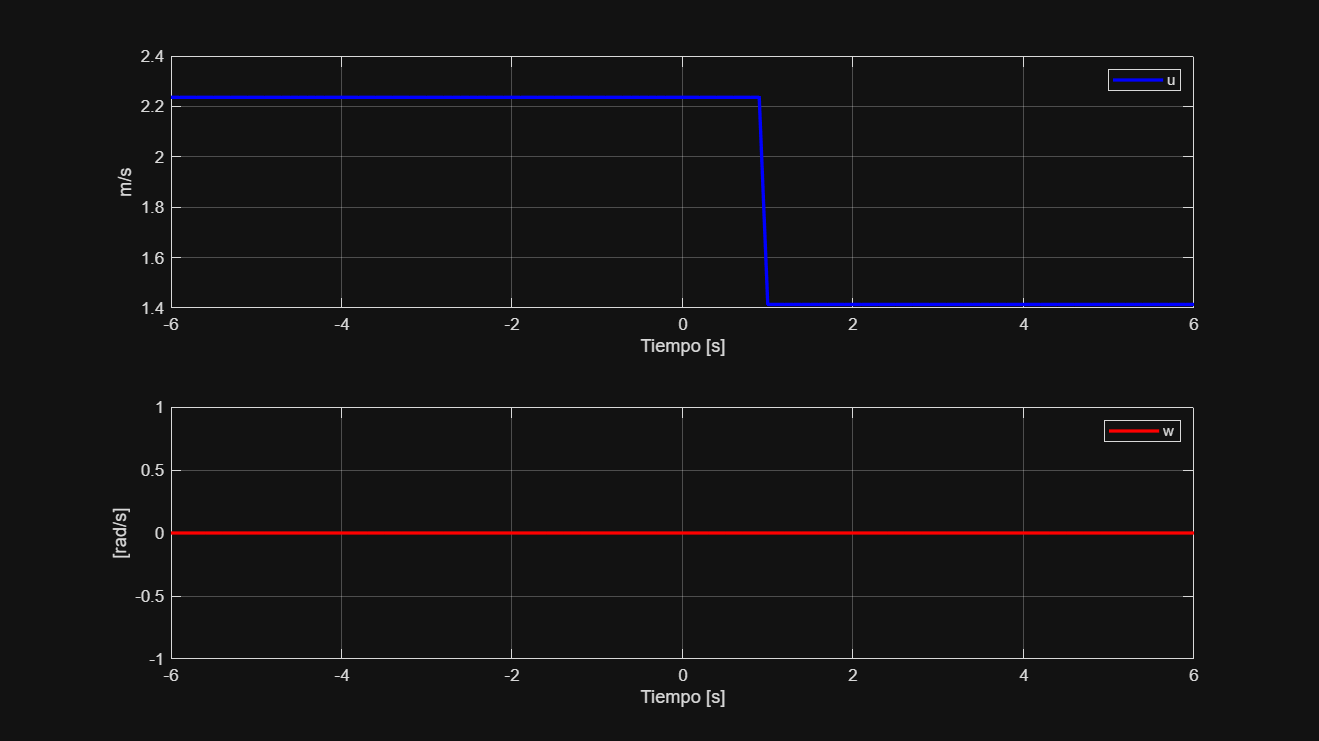


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph=figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(t,u,'b','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('m/s'),legend('u')

subplot(212)
plot(t,w,'r','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w')

Algunas de las razones por las que las gráficas pudieron no haber salido, podrían incluir divisiones sobre cero o cambios que los métodos numéricos no son capaces de detectar por el tiempo de muestreo, o como en el caso de la última, que la velocidad angular se vuelve cero, por lo que no tiene manera de cambiar entre trozos, además en el caso de la última, sería una función discontinua como en el cambio de 2x a 2x +1, y es más difícil que se pueda procesar esto.